# El Churro

## Section

r1 = 30;
r2 = 10;
p = 1;
x = linspace(0,5);

R1 = r1+2*r2/pi*asin(sin(2*pi/p*x))

R1 =    30.0000   32.0202   34.0404   36.0606   38.0808   39.8990   37.8788   35.8586   33.8384   31.8182   29.7980   27.7778   25.7576   23.7374   21.7172   20.3030   22.3232   24.3434   26.3636   28.3838   30.4040   32.4242   34.4444   36.4646   38.4848   39.4949   37.4747   35.4545   33.4343   31.4141   29.3939   27.3737   25.3535   23.3333   21.3131   20.7071   22.7273   24.7475   26.7677   28.7879   30.8081   32.8283   34.8485   36.8687   38.8889   39.0909   37.0707   35.0505   33.0303   31.0101


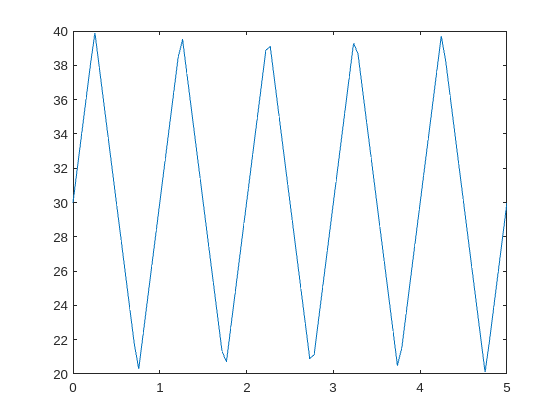


plot(x,R1)


th = linspace(0,2*pi);

X = R1.*cos(th)

X =    30.0000   31.9557   33.7665   35.4089   36.8603   37.9069   35.1655   32.3777   29.5697   26.7672   23.9954   21.2790   18.6416   16.1060   13.6938   11.7769   11.7694   11.4967   10.9519   10.1298    9.0276    7.6443    5.9812    4.0417    1.8312   -0.6266   -2.9699   -5.0457   -6.8476   -8.3710   -9.6138  -10.5757  -11.2587  -11.6667  -11.8058  -12.5404  -14.8832  -17.3597  -19.9490  -22.6288  -25.3759  -28.1661  -30.9746  -33.7757  -36.5436  -37.5075  -36.1599  -34.6102  -32.8807  -30.9945


Y = R1.*sin(th)

Y =          0    2.0308    4.3093    6.8245    9.5639   12.4498   14.0781   15.4118   16.4521   17.2022   17.6675   17.8552   17.7748   17.4373   16.8557   16.5384   18.9686   21.4576   23.9812   26.5147   29.0329   31.5103   33.9212   36.2400   38.4413   39.4900   37.3569   35.0937   32.7256   30.2783   27.7773   25.2483   22.7166   20.2073   17.7447   16.4779   17.1761   17.6374   17.8479   17.7955   17.4700   16.8631   15.9685   14.7818   13.3008   11.0132    8.1671    5.5380    3.1397    0.9839


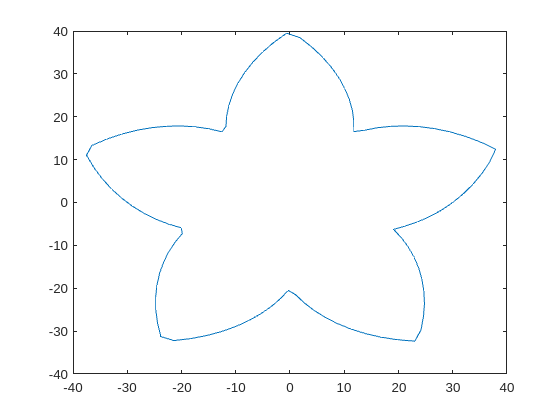


plot(X,Y)

## Rotation

syms ph th A B alpha
%alpha = asin(r2*2); %TODO: generalize in case of different r2

normal = [cos(th),sin(th),0]

$$normal = \left(\begin{array}{ccc} \cos\left(\mathrm{th}\right) & \sin\left(\mathrm{th}\right) & 0 \end{array}\right)$$


roty = [ cos(ph) 0 sin(ph);
            0 1 0;
         -sin(ph) 0 cos(ph)]

$$roty = \left(\begin{array}{ccc} \cos\left(\mathrm{ph}\right) & 0 & \sin\left(\mathrm{ph}\right)\\ 0 & 1 & 0\\ -\sin\left(\mathrm{ph}\right) & 0 & \cos\left(\mathrm{ph}\right) \end{array}\right)$$

rotx = [1 0 0;
        0 cos(A) sin(A);
        0 -sin(A) cos(A)]

$$rotx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(A\right) & \sin\left(A\right)\\ 0 & -\sin\left(A\right) & \cos\left(A\right) \end{array}\right)$$

rotz = [cos(B) sin(B) 0;
        -sin(B) cos(B) 0;
            0 0 1]

$$rotz = \left(\begin{array}{ccc} \cos\left(B\right) & \sin\left(B\right) & 0\\ -\sin\left(B\right) & \cos\left(B\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

n_s = simplify(normal*roty*rotx*rotz)

$$n\_s = \begin{array}{l} \left(\begin{array}{ccc} \cos\left(B\right)\,\cos\left(\mathrm{ph}\right)\,\cos\left(\mathrm{th}\right)-\sin\left(B\right)\,\sigma_{1} & \cos\left(B\right)\,\sigma_{1}+\sin\left(B\right)\,\cos\left(\mathrm{ph}\right)\,\cos\left(\mathrm{th}\right) & \sin\left(A\right)\,\sin\left(\mathrm{th}\right)+\cos\left(A\right)\,\cos\left(\mathrm{th}\right)\,\sin\left(\mathrm{ph}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(A\right)\,\sin\left(\mathrm{th}\right)-\sin\left(A\right)\,\cos\left(\mathrm{th}\right)\,\sin\left(\mathrm{ph}\right) \end{array}$$


L =simplify(dot(n_s,[0,1,-1]))

$$L = \cos\left(\bar{B}\right)\,\left(\cos\left(\bar{A}\right)\,\sin\left(\bar{\mathrm{th}}\right)-\sin\left(\bar{A}\right)\,\cos\left(\bar{\mathrm{th}}\right)\,\sin\left(\bar{\mathrm{ph}}\right)\right)-\sin\left(\bar{A}\right)\,\sin\left(\bar{\mathrm{th}}\right)-\cos\left(\bar{A}\right)\,\cos\left(\bar{\mathrm{th}}\right)\,\sin\left(\bar{\mathrm{ph}}\right)+\sin\left(\bar{B}\right)\,\cos\left(\bar{\mathrm{ph}}\right)\,\cos\left(\bar{\mathrm{th}}\right)$$

p = 5

p = 5

360/(p)

ans = 72